# Analysis of Stochastic Processes

## Assignment 3: Time - Series Analysis - Part III (Regression Analysis)

Jonas Benjamín de Seriis, 0515623;

Shuo Li, 515067

Luke Joshua Pugin, 0411499;

Víctor Alejandro Reinoso Rojas, 0479301; 

11.12.2025 - WiSe 25/26

### Task 1. Linear Trend Models

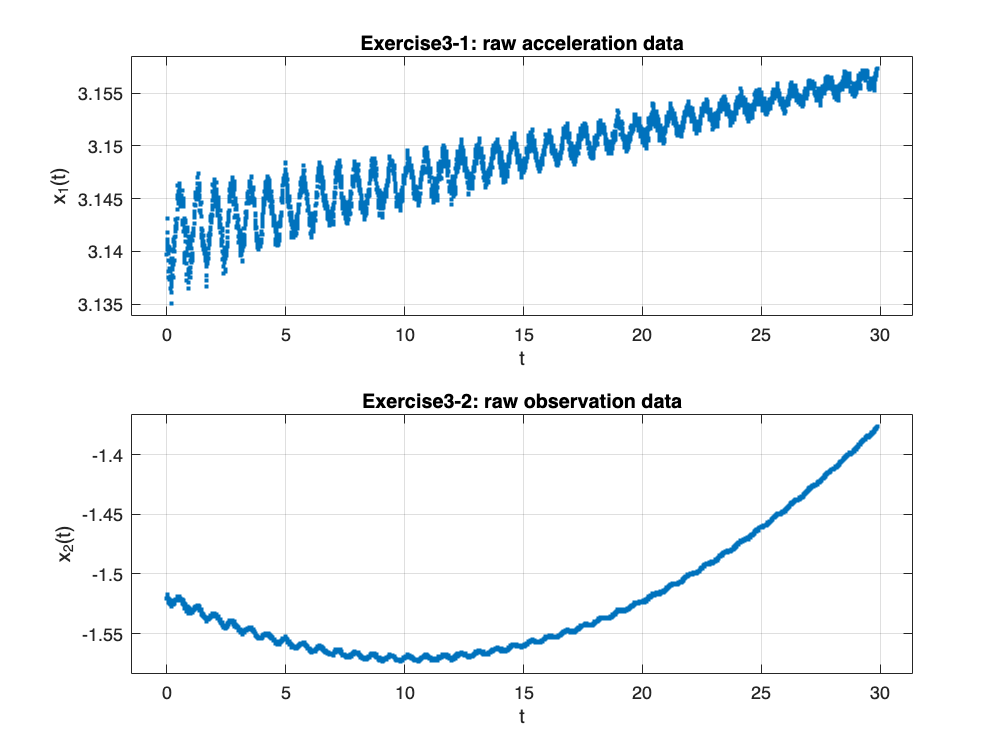

clc; clear; close all;

%% === Load data ===
data1 = load('Exercise3-1.txt');   % [t, x1]
data2 = load('Exercise3-2.txt');   % [t, x2]

t1 = data1(:,1);   x1 = data1(:,2);
t2 = data2(:,1);   x2 = data2(:,2);

%% === Helper for "bigger" axes (add 5% margin) ===
padlim = @(x) [min(x) - 0.05*(max(x)-min(x)), ...
               max(x) + 0.05*(max(x)-min(x))];

%% === Raw plots ===
figure;
subplot(2,1,1)
plot(t1, x1, '.', 'MarkerSize', 6); grid on;
xlabel('t'); ylabel('x_1(t)');
title('Exercise3-1: raw acceleration data');
xlim(padlim(t1)); ylim(padlim(x1));

subplot(2,1,2)
plot(t2, x2, '.', 'MarkerSize', 6); grid on;
xlabel('t'); ylabel('x_2(t)');
title('Exercise3-2: raw observation data');
xlim(padlim(t2)); ylim(padlim(x2));

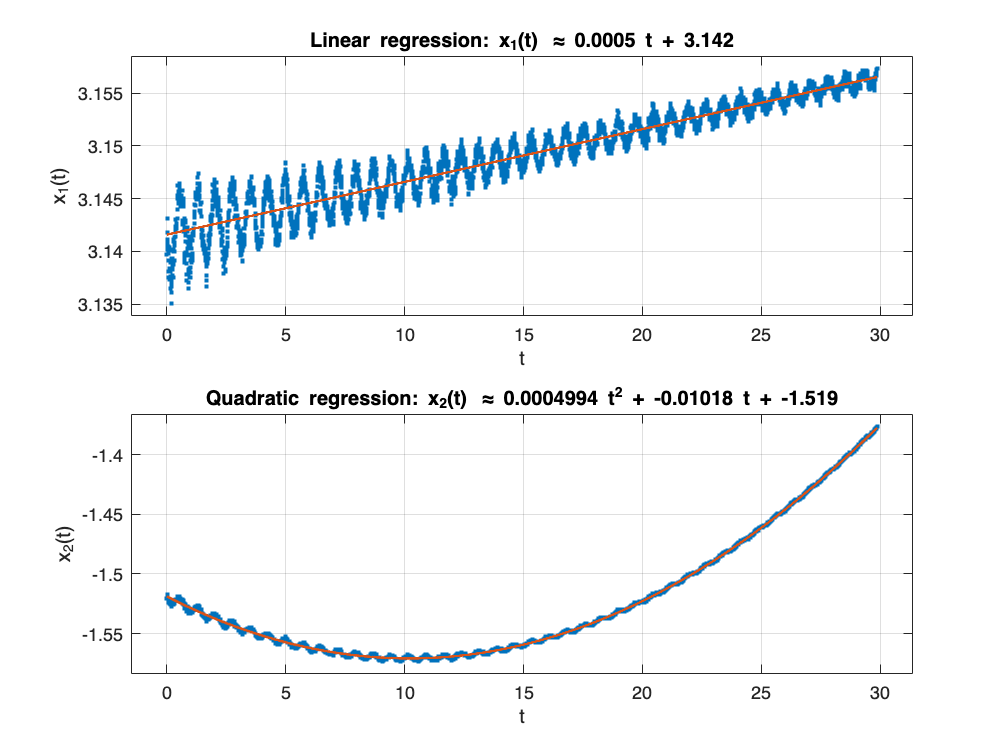


%% === Regression model 1: linear for Exercise3-1 ===
% reg1(t) = a1 * t + b1
A1 = [t1, ones(size(t1))];          % [a1, b1]
beta1 = (A1' * A1) \ (A1' * x1);
a1 = beta1(1); b1 = beta1(2);

x1_fit = A1 * beta1;                % regression values
x1_det = x1 - x1_fit;               % detrended series

%% === Regression model 2: quadratic for Exercise3-2 ===
% reg2(t) = a2 * t^2 + b2 * t + c2
A2 = [t2.^2, t2, ones(size(t2))];   % [a2, b2, c2]
beta2 = (A2' * A2) \ (A2' * x2);
a2 = beta2(1); b2 = beta2(2); c2 = beta2(3);

x2_fit = A2 * beta2;                % regression values
x2_det = x2 - x2_fit;               % detrended series

%% === Plot regression with a bit more margin ===
figure;

subplot(2,1,1)
plot(t1, x1, '.', 'MarkerSize', 6); hold on;
plot(t1, x1_fit, 'LineWidth', 1.5);
grid on;
xlabel('t'); ylabel('x_1(t)');
title(sprintf('Linear regression: x_1(t) \\approx %.4g t + %.4g', a1, b1));
xlim(padlim(t1)); ylim(padlim([x1; x1_fit]));

subplot(2,1,2)
plot(t2, x2, '.', 'MarkerSize', 6); hold on;
plot(t2, x2_fit, 'LineWidth', 1.5);
grid on;
xlabel('t'); ylabel('x_2(t)');
title(sprintf('Quadratic regression: x_2(t) \\approx %.4g t^2 + %.4g t + %.4g', ...
              a2, b2, c2));
xlim(padlim(t2)); ylim(padlim([x2; x2_fit]));

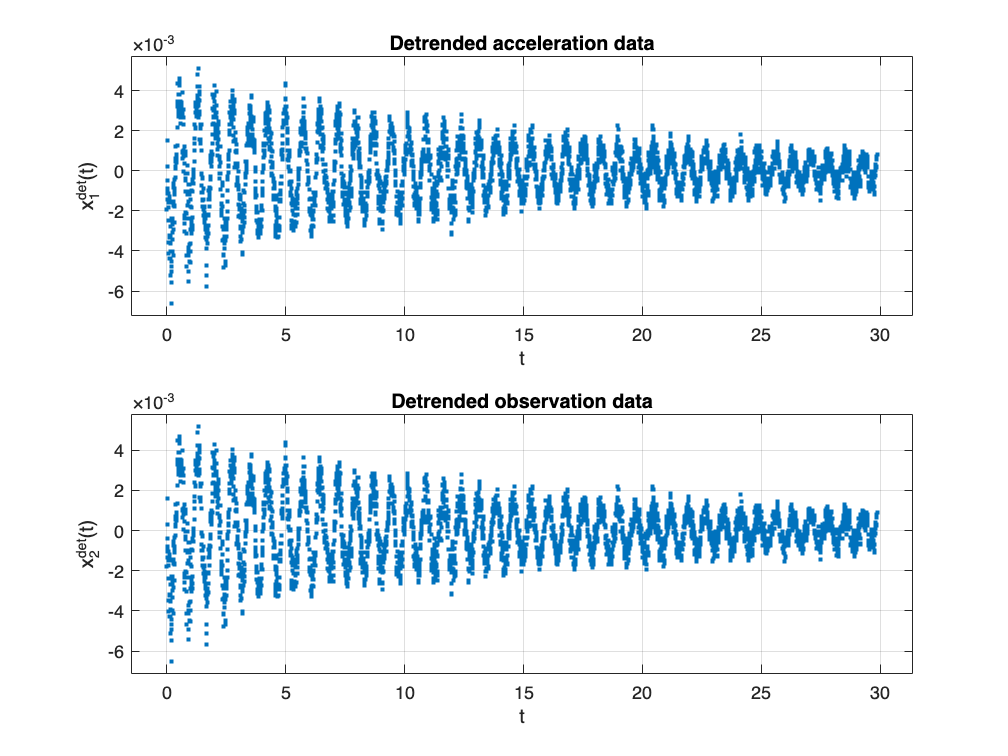


%% === Plot detrended series ===
figure;

subplot(2,1,1)
plot(t1, x1_det, '.', 'MarkerSize', 6); grid on;
xlabel('t'); ylabel('x_1^{det}(t)');
title('Detrended acceleration data');
xlim(padlim(t1)); ylim(padlim(x1_det));

subplot(2,1,2)
plot(t2, x2_det, '.', 'MarkerSize', 6); grid on;
xlabel('t'); ylabel('x_2^{det}(t)');
title('Detrended observation data');
xlim(padlim(t2)); ylim(padlim(x2_det));

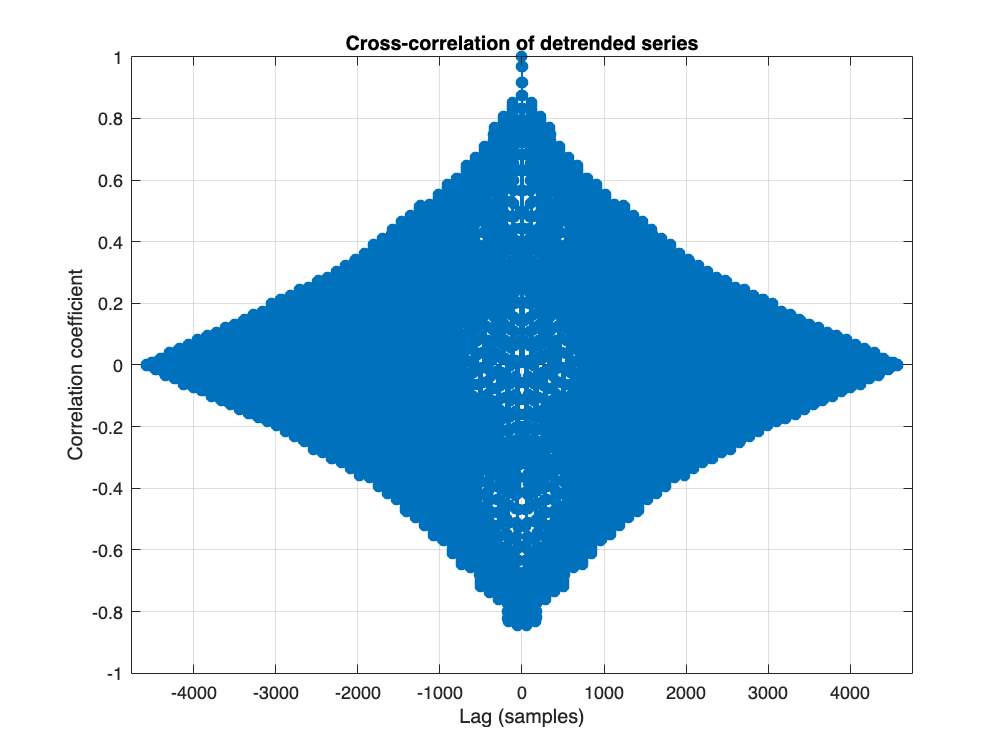


%% === Cross-correlation of detrended signals (for the interpretation) ===
[rc, lags] = xcorr(x1_det, x2_det, 'coeff');

figure;
stem(lags, rc, 'filled'); grid on;
xlabel('Lag (samples)');
ylabel('Correlation coefficient');
title('Cross-correlation of detrended series');


[rc_max, idx_max] = max(rc);
lag_max = lags(idx_max);
fprintf('Max cross-correlation = %.4f at lag = %d\n', rc_max, lag_max);

Max cross-correlation = 0.9996 at lag = 0


### Task 2. Linear Trend Models

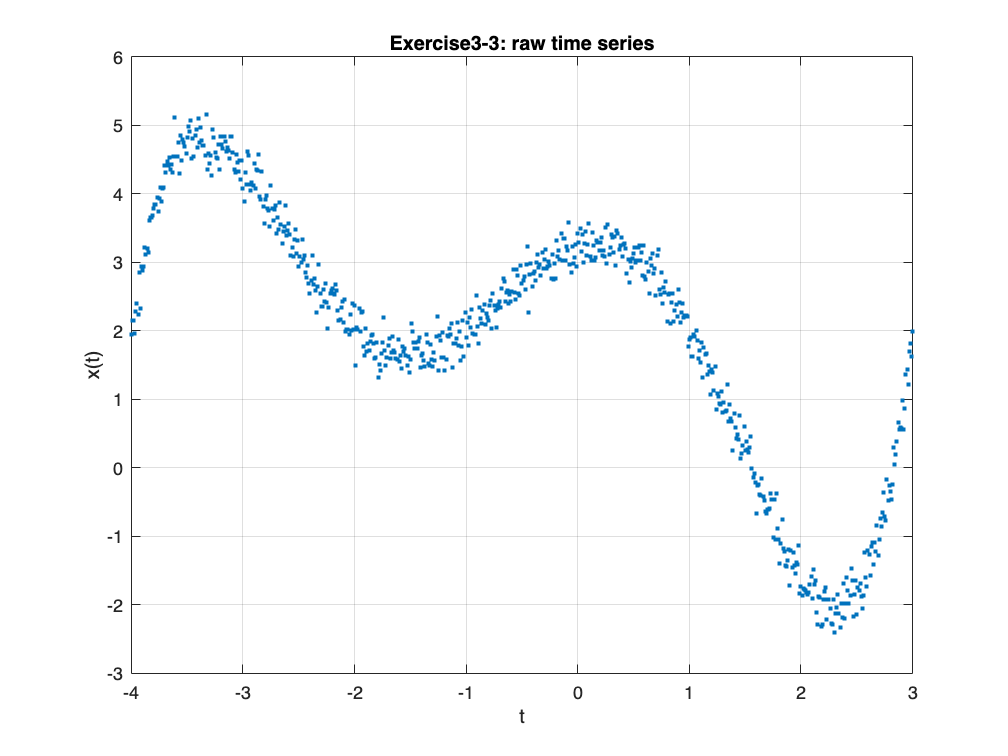

clc; clear; close all;

%% ==============================================================
%  Task 2 – Polynomial trend estimation with significance tests
%  Data: Exercise3-3.txt  (col 1: time t, col 2: x(t))
%  Goal:
%   - Start with a straight line, then increase polynomial degree.
%   - At each step:
%       * Estimate coefficients by least squares
%       * Plot residuals as a bar plot
%       * Test each coefficient with a t-test (alpha = 5%)
%   - Stop when the highest-degree coefficient is NOT significant.
%   - Finally:
%       * Plot data + chosen polynomial trend
%       * Plot detrended series (data minus trend)
% ==============================================================

%% === Parameters ===
alpha = 0.05;     % Significance level for the t-tests

%% === Load data ===
data = load('Exercise3-3.txt');    % [t, x(t)]
t = data(:,1);
x = data(:,2);
n = length(t);

%% === Quick look at the raw time series ===
figure;
plot(t, x, '.', 'MarkerSize', 6); grid on;
xlabel('t');
ylabel('x(t)');
title('Exercise3-3: raw time series');

Trying polynomial degree: 1


Model: x(t) = beta_0 + beta_1 t + ... + beta_1 t^1


  s0 (empirical std. dev.) = 1.1650


  t_crit (alpha = 0.05, dof = 699) = 1.963


  Coefficients and t-values:


    beta_0 = +1.600363  ± 0.045326   t = +35.308   SIGNIFICANT
    beta_1 = -0.730708  ± 0.021745   t = -33.604   SIGNIFICANT


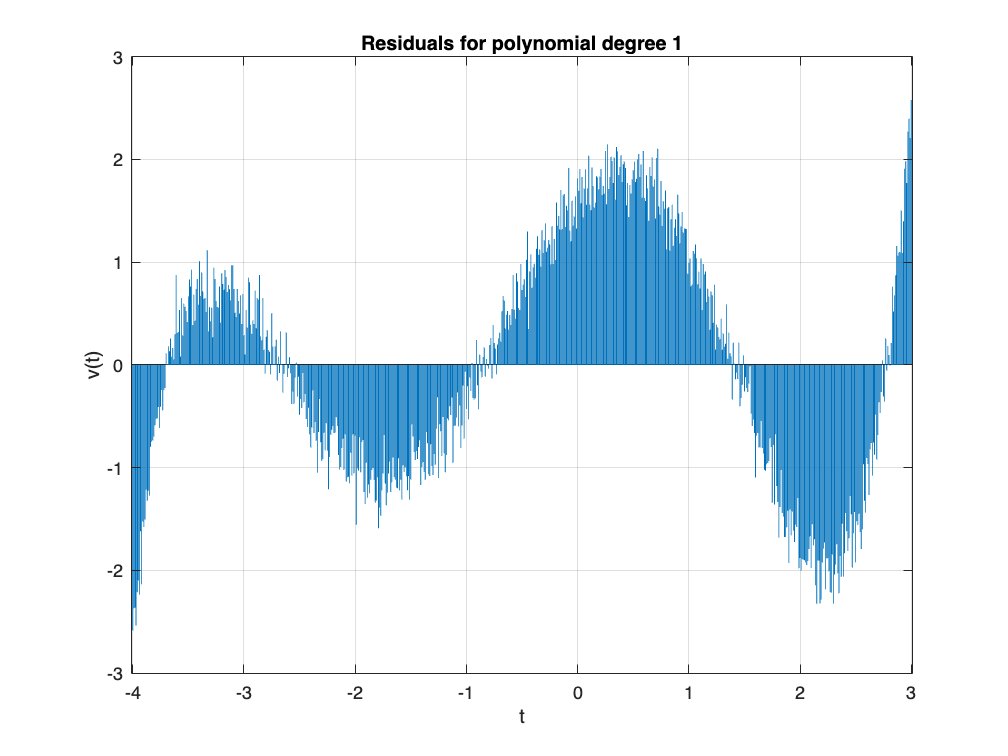

  --> The highest-degree coefficient (degree 1) IS significant.


      It is allowed to increase the degree further (if needed).


Trying polynomial degree: 2


Model: x(t) = beta_0 + beta_1 t + ... + beta_2 t^2


  s0 (empirical std. dev.) = 1.1045


  t_crit (alpha = 0.05, dof = 698) = 1.963


  Coefficients and t-values:


    beta_0 = +1.991229  ± 0.061357   t = +32.453   SIGNIFICANT
    beta_1 = -0.832364  ± 0.023553   t = -35.340   SIGNIFICANT
    beta_2 = -0.101656  ± 0.011390   t =  -8.925   SIGNIFICANT


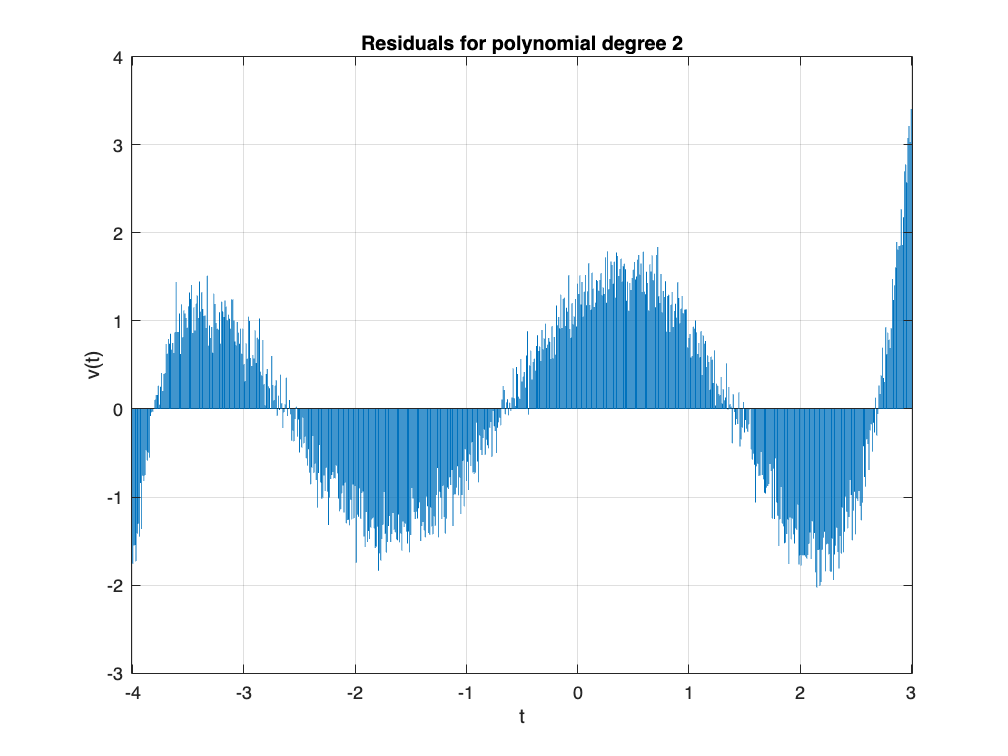

  --> The highest-degree coefficient (degree 2) IS significant.


      It is allowed to increase the degree further (if needed).


Trying polynomial degree: 3


Model: x(t) = beta_0 + beta_1 t + ... + beta_3 t^3


  s0 (empirical std. dev.) = 1.0702


  t_crit (alpha = 0.05, dof = 697) = 1.963


  Coefficients and t-values:


    beta_0 = +2.141924  ± 0.063429   t = +33.769   SIGNIFICANT
    beta_1 = -0.552137  ± 0.047022   t = -11.742   SIGNIFICANT
    beta_2 = -0.165142  ± 0.014441   t = -11.435   SIGNIFICANT
    beta_3 = -0.042324  ± 0.006209   t =  -6.816   SIGNIFICANT


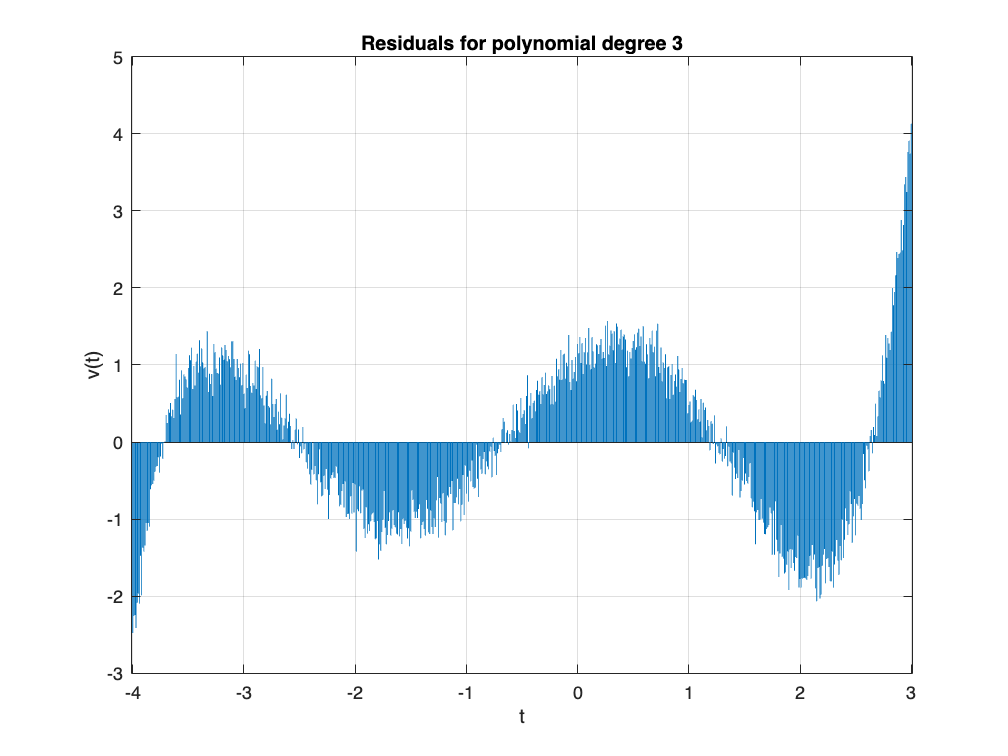

  --> The highest-degree coefficient (degree 3) IS significant.


      It is allowed to increase the degree further (if needed).


Trying polynomial degree: 4


Model: x(t) = beta_0 + beta_1 t + ... + beta_4 t^4


  s0 (empirical std. dev.) = 1.0315


  t_crit (alpha = 0.05, dof = 696) = 1.963


  Coefficients and t-values:


    beta_0 = +2.400872  ± 0.070503   t = +34.053   SIGNIFICANT
    beta_1 = -0.802692  ± 0.056645   t = -14.170   SIGNIFICANT
    beta_2 = -0.390716  ± 0.033612   t = -11.624   SIGNIFICANT
    beta_3 = +0.007637  ± 0.009041   t =  +0.845   not significant
    beta_4 = +0.024981  ± 0.003388   t =  +7.373   SIGNIFICANT


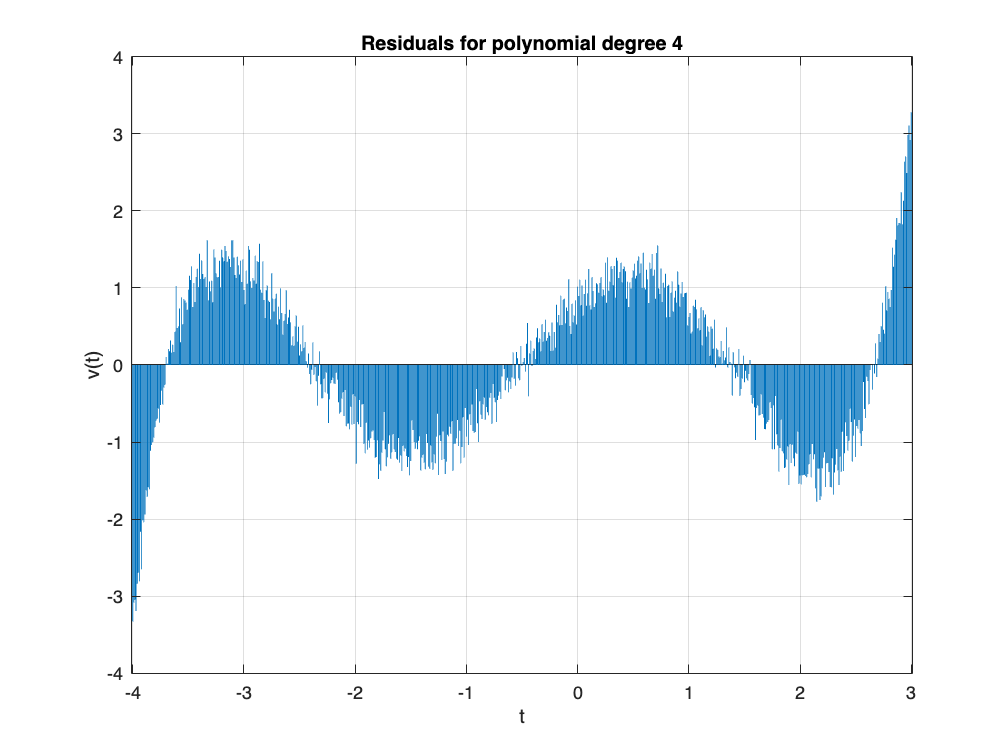

  --> The highest-degree coefficient (degree 4) IS significant.


      It is allowed to increase the degree further (if needed).


Trying polynomial degree: 5


Model: x(t) = beta_0 + beta_1 t + ... + beta_5 t^5


  s0 (empirical std. dev.) = 0.1974


  t_crit (alpha = 0.05, dof = 695) = 1.963


  Coefficients and t-values:


    beta_0 = +3.212410  ± 0.014765   t = +217.573   SIGNIFICANT
    beta_1 = +0.492861  ± 0.014463   t = +34.078   SIGNIFICANT
    beta_2 = -1.348379  ± 0.009563   t = -140.993   SIGNIFICANT
    beta_3 = -0.547781  ± 0.004454   t = -122.978   SIGNIFICANT
    beta_4 = +0.149516  ± 0.001126   t = +132.810   SIGNIFICANT
    beta_5 = +0.049814  ± 0.000368   t = +135.317   SIGNIFICANT


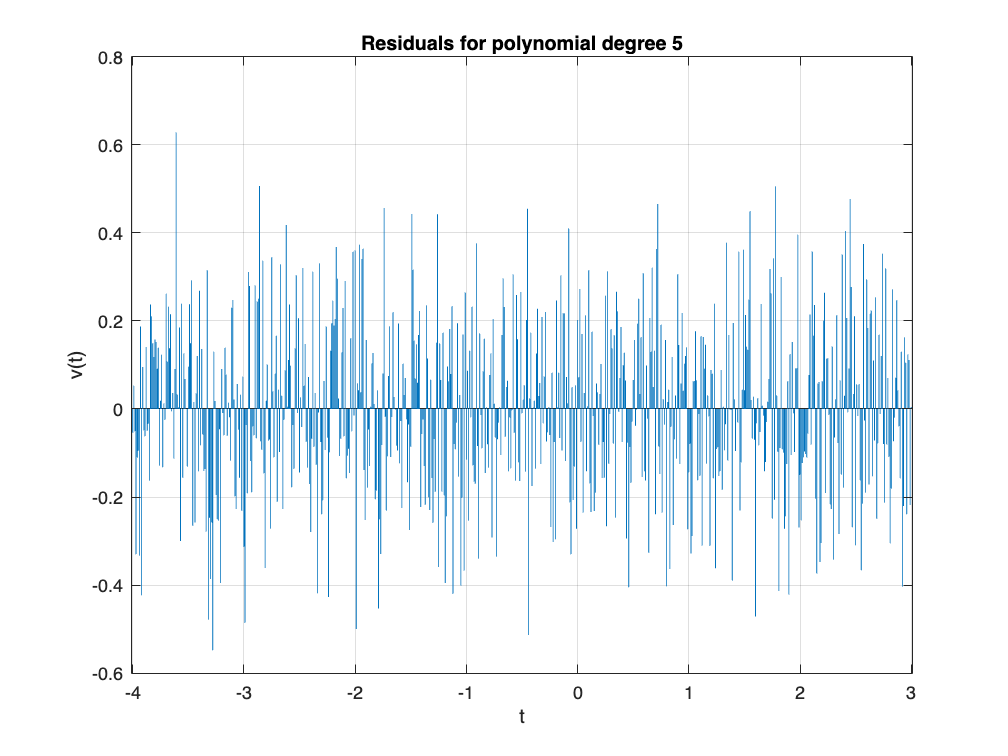

  --> The highest-degree coefficient (degree 5) IS significant.


      It is allowed to increase the degree further (if needed).


Trying polynomial degree: 6


Model: x(t) = beta_0 + beta_1 t + ... + beta_6 t^6


  s0 (empirical std. dev.) = 0.1975


  t_crit (alpha = 0.05, dof = 694) = 1.963


  Coefficients and t-values:


    beta_0 = +3.212275  ± 0.015608   t = +205.809   SIGNIFICANT
    beta_1 = +0.493200  ± 0.019226   t = +25.653   SIGNIFICANT
    beta_2 = -1.348130  ± 0.013347   t = -101.009   SIGNIFICANT
    beta_3 = -0.547955  ± 0.007877   t = -69.560   SIGNIFICANT
    beta_4 = +0.149443  ± 0.002948   t = +50.701   SIGNIFICANT
    beta_5 = +0.049831  ± 0.000728   t = +68.404   SIGNIFICANT
    beta_6 = +0.000006  ± 0.000209   t =  +0.027   not significant


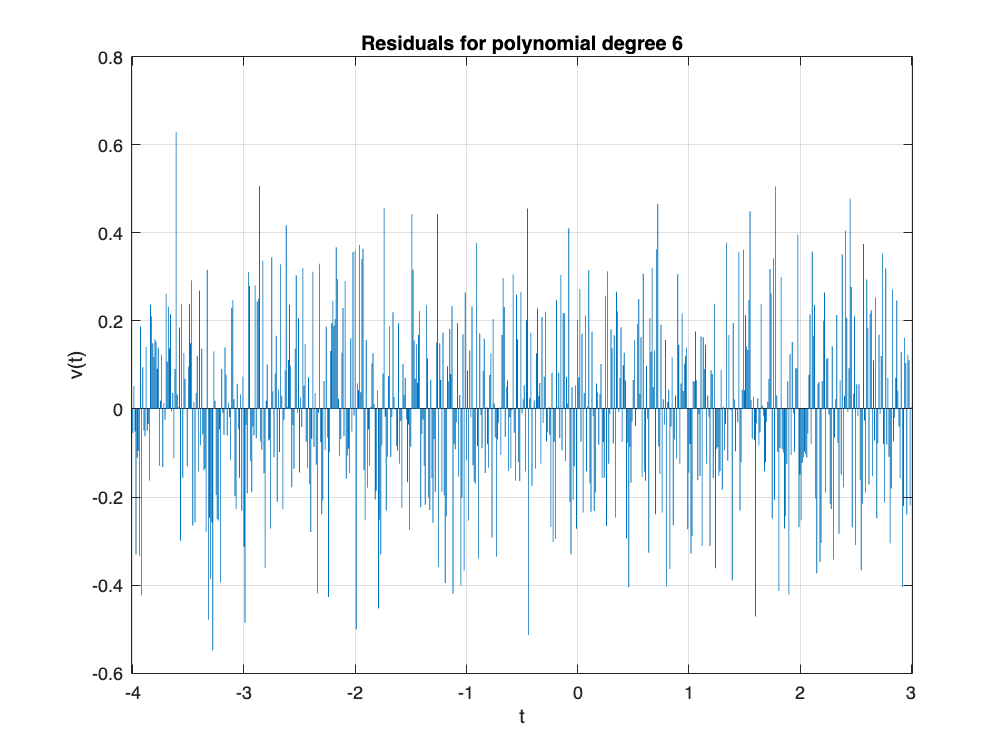

  --> The highest-degree coefficient (degree 6) is NOT significant.


      According to the t-test, this is stopped at degree 5.



%% === Helper: build design matrix A for a polynomial of degree "deg"
%   A(:,1) = 1, A(:,2) = t, ..., A(:,deg+1) = t^deg
%   (bsxfun just makes sure dimensions match nicely.)
buildA = @(t, deg) bsxfun(@power, t(:), 0:deg);

maxDegree = 6;   % Safety upper limit (it could stop earlier)
results   = struct();

bestDegree = [];   % It will be filled once criterion is met

for deg = 1:maxDegree
    
    fprintf('\n====================================================\n');
    fprintf('Trying polynomial degree: %d\n', deg);
    fprintf('Model: x(t) = beta_0 + beta_1 t + ... + beta_%d t^%d\n', deg, deg);
    
    % --- Design matrix for this degree ---
    A = buildA(t, deg);          % size: n x (deg+1)
    u = deg + 1;                 % number of unknown coefficients beta_0,...,beta_deg
    
    % --- Least-squares solution: beta = (A^T A)^(-1) A^T x ---
    N    = A' * A;               % normal matrix
    beta = N \ (A' * x);         % solution of normal equations
    
    % --- Residuals and a-posteriori variance factor ---
    x_hat = A * beta;            % fitted values
    v     = x - x_hat;           % residuals
    dof   = n - u;               % degrees of freedom
    s0    = sqrt( (v' * v) / dof );  % empirical standard deviation of unit weight
    
    % --- Covariance of beta and standard deviations ---
    Qxx    = inv(N);                     % cofactor matrix of beta
    s_beta = s0 * sqrt(diag(Qxx));       % standard deviations of beta
    t_val  = beta ./ s_beta;             % t-values for each coefficient
    
    % --- t critical for two-sided test with alpha and "dof" ---
    % If tinv is not available, you could approximate with 1.96 for large dof.
    tcrit = tinv(1 - alpha/2, dof);
    
    fprintf('  s0 (empirical std. dev.) = %.4f\n', s0);
    fprintf('  t_crit (alpha = %.2f, dof = %d) = %.3f\n', alpha, dof, tcrit);
    fprintf('  Coefficients and t-values:\n');
    for k = 0:deg
        sigFlag = abs(t_val(k+1)) > tcrit;
        fprintf('    beta_%d = %+ .6f  ± %.6f   t = %+7.3f   %s\n', ...
            k, beta(k+1), s_beta(k+1), t_val(k+1), ...
            ternary(sigFlag,'SIGNIFICANT','not significant'));
    end
    
    % --- Bar plot of residuals for visual inspection ---
    figure;
    bar(t, v); grid on;
    xlabel('t');
    ylabel('v(t)');
    title(sprintf('Residuals for polynomial degree %d', deg));
    
    % Store results for later comparison / plotting
    results(deg).deg    = deg;
    results(deg).beta   = beta;
    results(deg).s0     = s0;
    results(deg).s_beta = s_beta;
    results(deg).t_val  = t_val;
    results(deg).tcrit  = tcrit;
    results(deg).v      = v;
    results(deg).dof    = dof;
    
    % --- Stopping criterion from the assignment ------------------
    %    It repeats the procedure until no further systematic effects in the
    %    residuals are visible and the newest coefficient is statistically
    %    not significant."
    %
    %    Second part can be checked automatically (last coefficient).
    lastCoeffSignificant = abs(t_val(end)) > tcrit;
    
    if ~lastCoeffSignificant
        % Highest-degree term is NOT significant -> degree-1 is enough
        if deg == 1
            % Already for a straight line the last coeff is not significant
            bestDegree = 1;
            fprintf('  --> The slope (beta_1) is not significant.\n');
            fprintf('      According to the t-test, a constant model would already be sufficient.\n');
        else
            bestDegree = deg - 1;
            fprintf('  --> The highest-degree coefficient (degree %d) is NOT significant.\n', deg);
            fprintf('      According to the t-test, this is stopped at degree %d.\n', bestDegree);
        end
        % Note: Still the residual plots should be looked to confirm that
        %       no obvious systematic structure remains.
        break;
    else
        fprintf('  --> The highest-degree coefficient (degree %d) IS significant.\n', deg);
        fprintf('      It is allowed to increase the degree further (if needed).\n');
    end
    
end

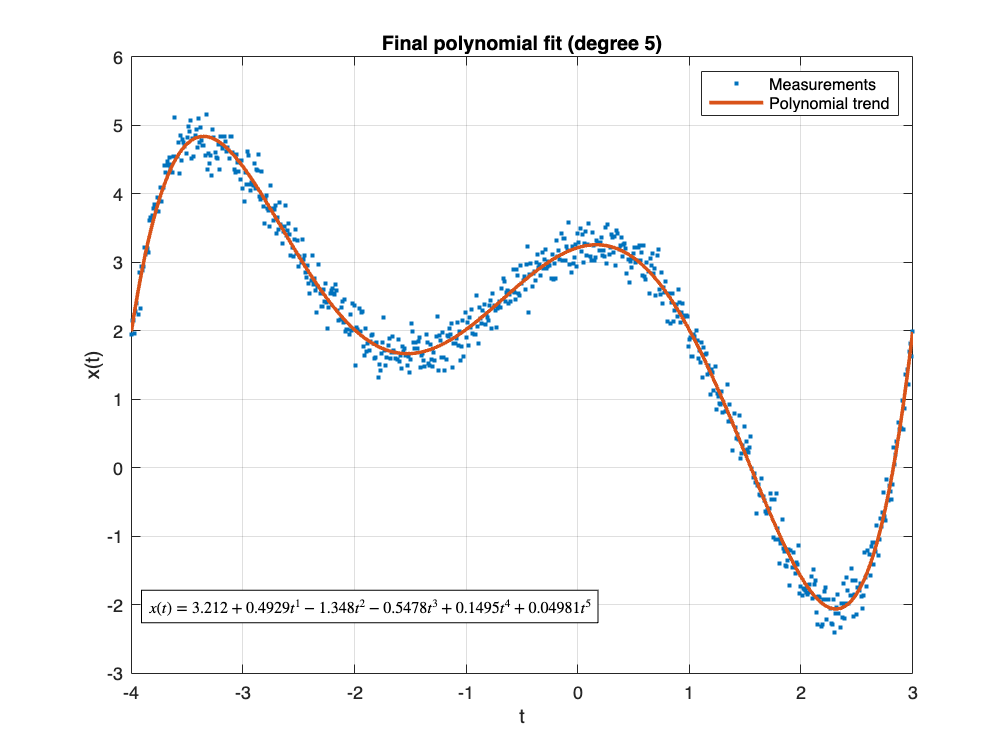


% If the loop is never broken up (all highest-degree coefficients significant),
% the maximum tested degree as the final model is taken.
if isempty(bestDegree)
    bestDegree = maxDegree;
    fprintf('\nAll tested degrees up to %d had significant highest-degree coefficients.\n', maxDegree);
    fprintf('Tentatively adoptted degree %d as the final model.\n', bestDegree);
end

% === Final model: data + polynomial trend ===
beta_best = results(bestDegree).beta;
A_best    = buildA(t, bestDegree);
x_fit_best = A_best * beta_best;
x_det_best = x - x_fit_best;   % detrended series

% Build a dense grid for a smooth trend curve
t_dense = linspace(min(t), max(t), 1000).';
A_dense = buildA(t_dense, bestDegree);
x_trend_dense = A_dense * beta_best;

%% -------- Generate polynomial equation as a string --------
poly_str = "$x(t) = ";
for k = 0:bestDegree
    coef = beta_best(k+1);
    if k == 0
        poly_str = poly_str + sprintf("%.4g", coef);
    else
        % positive or negative sign with correct spacing
        if coef >= 0
            poly_str = poly_str + sprintf(" + %.4g t^{%d}", coef, k);
        else
            poly_str = poly_str + sprintf(" - %.4g t^{%d}", abs(coef), k);
        end
    end
end
poly_str = poly_str + "$";   % close LaTeX math environment

%% -------- Nice plot: data points + smooth polynomial trend --------
figure;
plot(t, x, '.', 'MarkerSize', 6); hold on;
plot(t_dense, x_trend_dense, 'LineWidth', 2);
grid on;
xlabel('t'); ylabel('x(t)');
title(sprintf('Final polynomial fit (degree %d)', bestDegree));
legend('Measurements','Polynomial trend','Location','northeast');

% Place equation in the LOWER LEFT corner of the figure
xpos = min(t) + 0.02*(max(t)-min(t));     % 2% from the left
ypos = min(x) + 0.05*(max(x)-min(x));     % 5% above the bottom

text(xpos, ypos, poly_str, 'Interpreter','latex', ...
     'FontSize', 9, ...
     'BackgroundColor','w', ...
     'EdgeColor','k');

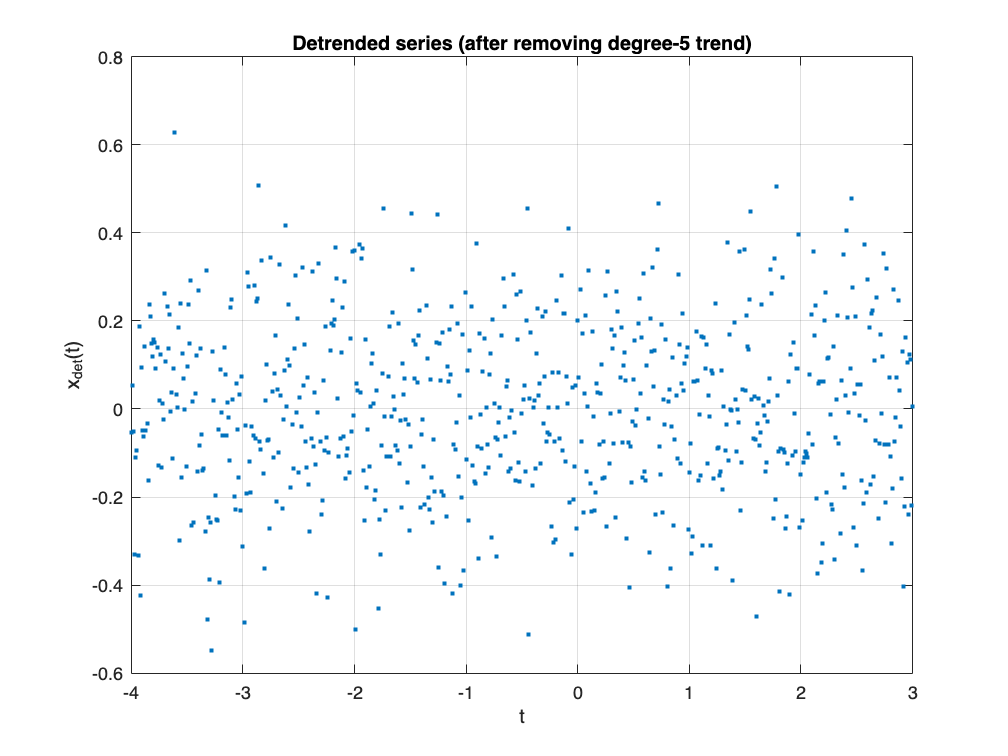




%% === Plot detrended series (data minus trend) ===
figure;
plot(t, x_det_best, '.', 'MarkerSize', 6); grid on;
xlabel('t');
ylabel('x_{det}(t)');
title(sprintf('Detrended series (after removing degree-%d trend)', bestDegree));


fprintf('\nFinal choice: polynomial degree %d.\n', bestDegree);


Final choice: polynomial degree 5.


fprintf('Use the residual plots to visually confirm that no systematic pattern remains.\n');

Use the residual plots to visually confirm that no systematic pattern remains.



%% ==============================================================
%  Local helper: "ternary" function for better printing
%  Returns a if cond is true, otherwise returns b.
% ==============================================================
function out = ternary(cond, a, b)
    if cond
        out = a;
    else
        out = b;
    end
end


### Task 3. Nonlinear trend models

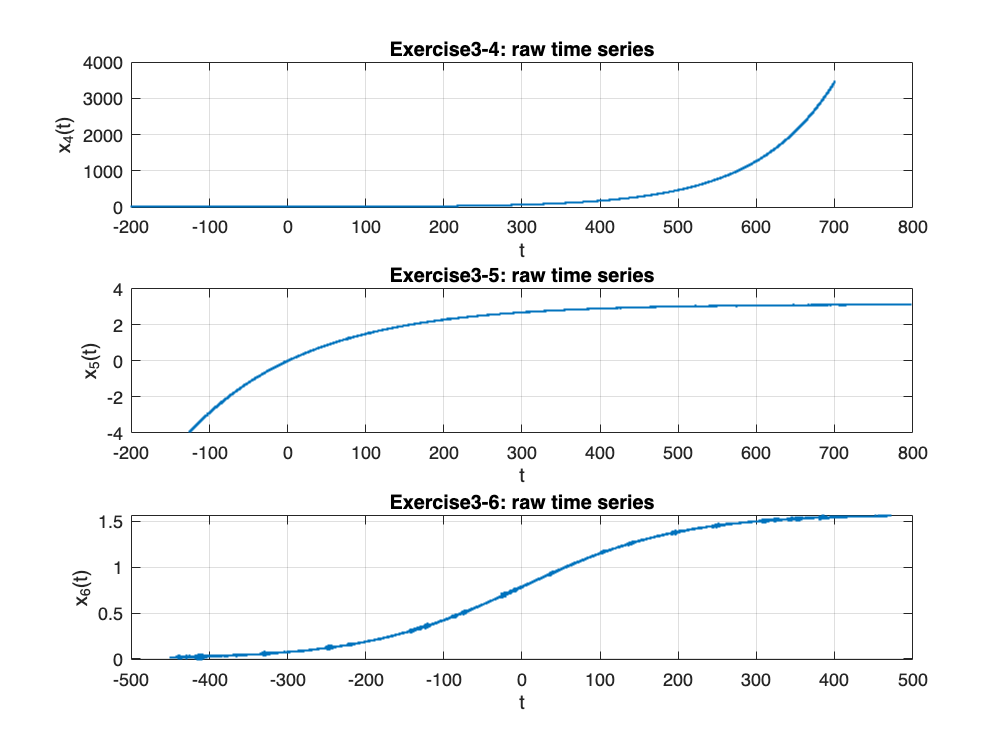

%% ================================================================
%  Task 3: Nonlinear trend models
%  Files: Exercise3-4.txt, Exercise3-5.txt, Exercise3-6.txt
%  The first column is time t, the second column is x(t).
%  The measurements x(t) are equally weighted and uncorrelated,
%  and the time t is treated as error-free.
% ================================================================

clc; clear; close all;

%% ---------- Helper: load data (comma as column separator) ----------
data4 = readmatrix('Exercise3-4.txt', 'Delimiter', ',');
data5 = readmatrix('Exercise3-5.txt', 'Delimiter', ',');
data6 = readmatrix('Exercise3-6.txt', 'Delimiter', ',');

t4 = data4(:,1); x4 = data4(:,2);
t5 = data5(:,1); x5 = data5(:,2);
t6 = data6(:,1); x6 = data6(:,2);

%% ================================================================
%  1) Plot raw time series
% ================================================================
figure;
subplot(3,1,1);
plot(t4, x4, '.', 'MarkerSize', 3); grid on;
xlabel('t'); ylabel('x_4(t)');
title('Exercise3-4: raw time series');

subplot(3,1,2);
plot(t5, x5, '.', 'MarkerSize', 3); grid on;
xlabel('t'); ylabel('x_5(t)');
title('Exercise3-5: raw time series');

subplot(3,1,3);
plot(t6, x6, '.', 'MarkerSize', 3); grid on;
xlabel('t'); ylabel('x_6(t)');
title('Exercise3-6: raw time series');


%% ================================================================
%  2) Series 4: Exponential trend  x_4(t) = a * exp(b t)
%     -> Linearizable by taking ln(x)
% ================================================================

% Only positive values are present, so log-transform is admissible
y4 = log(x4);

% Linear model: y4 = ln(a) + b * t
A4 = [ones(size(t4)) t4];
beta4 = A4 \ y4;              % least-squares solution

a4 = exp(beta4(1));
b4 = beta4(2);

% Reconstruct exponential trend and detrended series
x4_trend = a4 * exp(b4 * t4);
x4_det   = x4 - x4_trend;

fprintf('--- Series 4: exponential model x(t) = a * exp(b t) ---\n');

--- Series 4: exponential model x(t) = a * exp(b t) ---


fprintf('a4 = %.6g\n', a4);

a4 = 3.1416


fprintf('b4 = %.6g\n\n', b4);

b4 = 0.01



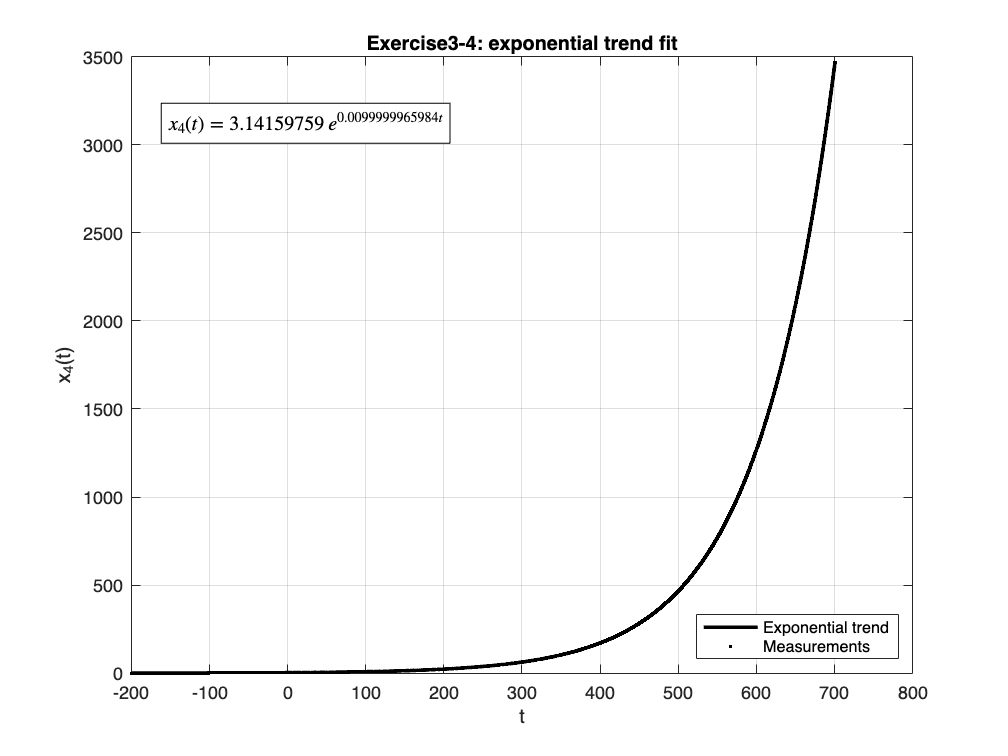


% Plot data + trend
figure;
plot(t4, x4_trend, 'LineWidth', 2, 'Color', [0 0 0]); hold on; % Trend line
plot(t4, x4, '.', 'MarkerSize', 5, 'Color', 'black');          % Data points

grid on;
xlabel('t');
ylabel('x_4(t)');
title('Exercise3-4: exponential trend fit');
legend('Exponential trend','Measurements','Location','southeast');

% -----------------------------------------------------------
% Insert model equation inside the figure
% -----------------------------------------------------------
% Build LaTeX string with estimated parameters
eq_str = sprintf('$x_4(t) = %.8f \\, e^{%.13f t}$', a4, b4);

% Choose a good position (10% from left, 85% from top)
xpos = min(t4) + 0.05 * (max(t4) - min(t4));
ypos = max(x4) - 0.10 * (max(x4) - min(x4));

% Draw the equation
text(xpos, ypos, eq_str, 'Interpreter', 'latex', ...
     'FontSize', 11, 'BackgroundColor', 'white', 'EdgeColor', 'black');

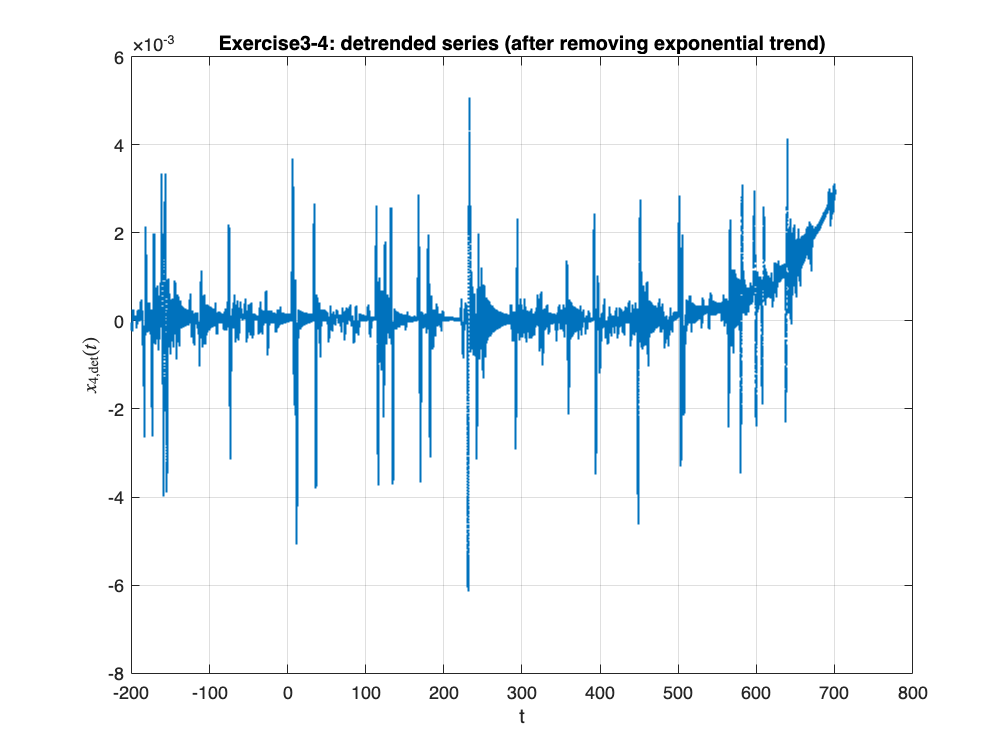


% Detrended series
figure;
plot(t4, x4_det, '.', 'MarkerSize', 3);
grid on;
xlabel('t');
ylabel('$x_{4,\mathrm{det}}(t)$', 'Interpreter', 'latex');
title('Exercise3-4: detrended series (after removing exponential trend)');


%% ================================================================
%  3) Series 5: Logistic trend with offset
%      x_5(t) = c + L / (1 + exp(-k (t - t0)))
%     Fully nonlinear in the parameters -> iterative LS (lsqcurvefit)
% ================================================================

% Logistic model function
logistic_offset = @(p, t) p(1) + p(2) ./ (1 + exp(-p(3) * (t - p(4))));
% p(1) = c   (offset)
% p(2) = L   (amplitude)
% p(3) = k   (growth rate)
% p(4) = t0  (center of transition)

% Initial guesses from data
c0_5  = min(x5);                  % lower asymptote approx.
L0_5  = max(x5) - min(x5);        % amplitude
k0_5  = 0.01;                     % rough growth rate guess
t0_5  = mean(t5);                 % center in time

p0_5 = [c0_5, L0_5, k0_5, t0_5];

% ---------------------------------------------------------------
% Nonlinear least-squares adjustment for the logistic-with-offset model.
%
% The function logistic_offset(p,t) is nonlinear in its parameters
% p = [c, L, k, t0]. Therefore, the parameter estimation cannot be obtained
% by a closed-form solution (as in the linear Gauss–Markov case) and must
% be solved iteratively.
%
% The MATLAB routine lsqcurvefit computes
%
%        p_hat = argmin_p  || x_obs - f(p,t) ||^2
%
% using a trust-region-reflective or Levenberg–Marquardt method,
% depending on the structure of the problem.
%
% Initial values p0_5 must be chosen to reflect the approximate scale
% of the data; unrealistic initial guesses may cause divergence or
% convergence to a non-physical local minimum.
%
% The empty brackets [] for lower and upper bounds indicate that no
% constraints are imposed on the parameters. Bounds could be added if
% physically motivated (e.g. positivity of L or k).
%
% The 'opts' structure disables intermediate command-window output,
% but may also be used to control tolerances, maximum iteration count,
% Jacobian usage, etc.
% ---------------------------------------------------------------

opts = optimoptions('lsqcurvefit', 'Display', 'off');
p5_hat = lsqcurvefit(logistic_offset, p0_5, t5, x5, [], [], opts);

c5  = p5_hat(1);
L5  = p5_hat(2);
k5  = p5_hat(3);
t0_5 = p5_hat(4);

fprintf('--- Series 5: logistic + offset model ---\n');

--- Series 5: logistic + offset model ---


fprintf('x_5(t) = c + L / (1 + exp(-k (t - t0)))\n');

x_5(t) = c + L / (1 + exp(-k (t - t0)))


fprintf('c  = %.6g\n', c5);

c  = -4284.7


fprintf('L  = %.6g\n', L5);

L  = 4287.84


fprintf('k  = %.6g\n', k5);

k  = 0.00650549


fprintf('t0 = %.6g\n\n', t0_5);

t0 = -1109.54



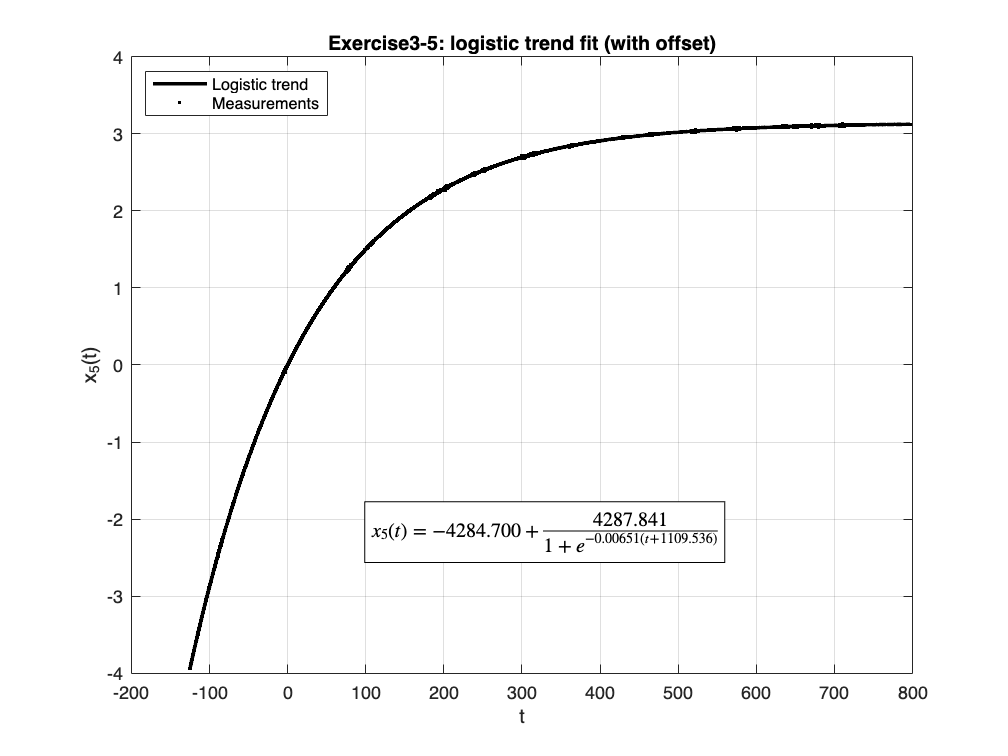


x5_trend = logistic_offset(p5_hat, t5);
x5_det   = x5 - x5_trend;

% Plot data + trend
figure;
plot(t5, x5_trend, 'LineWidth', 2, 'Color', [0 0 0]); hold on;   % Trend line
plot(t5, x5, '.', 'MarkerSize', 5, 'Color', 'black');            % Data points

grid on;
xlabel('t'); ylabel('x_5(t)');
title('Exercise3-5: logistic trend fit (with offset)');
legend('Logistic trend','Measurements','Location','northwest');

% -----------------------------------------------------------
% Insert logistic equation inside the figure (Series 5)
% -----------------------------------------------------------

% Decide sign for (t ± t0)
if t0_5 >= 0
    sign_char = '-';
    t0_abs    = t0_5;
else
    sign_char = '+';
    t0_abs    = abs(t0_5);
end

% Build LaTeX equation string
eq_str_5 = sprintf( ...
    '$x_5(t) = %.3f + \\frac{%.3f}{1 + e^{-%.5f (t %c %.3f)}}$', ...
    c5, L5, k5, sign_char, t0_abs);

% ---------- Place equation bottom-right ----------
xpos = max(t5) - 0.75 * (max(t5) - min(t5));   
ypos = min(x5) + 0.25 * (max(x5) - min(x5)); 

% Draw the equation
text(xpos, ypos, eq_str_5, ...
     'Interpreter', 'latex', ...
     'FontSize', 11, ...
     'BackgroundColor', 'white', ...
     'EdgeColor', 'black');

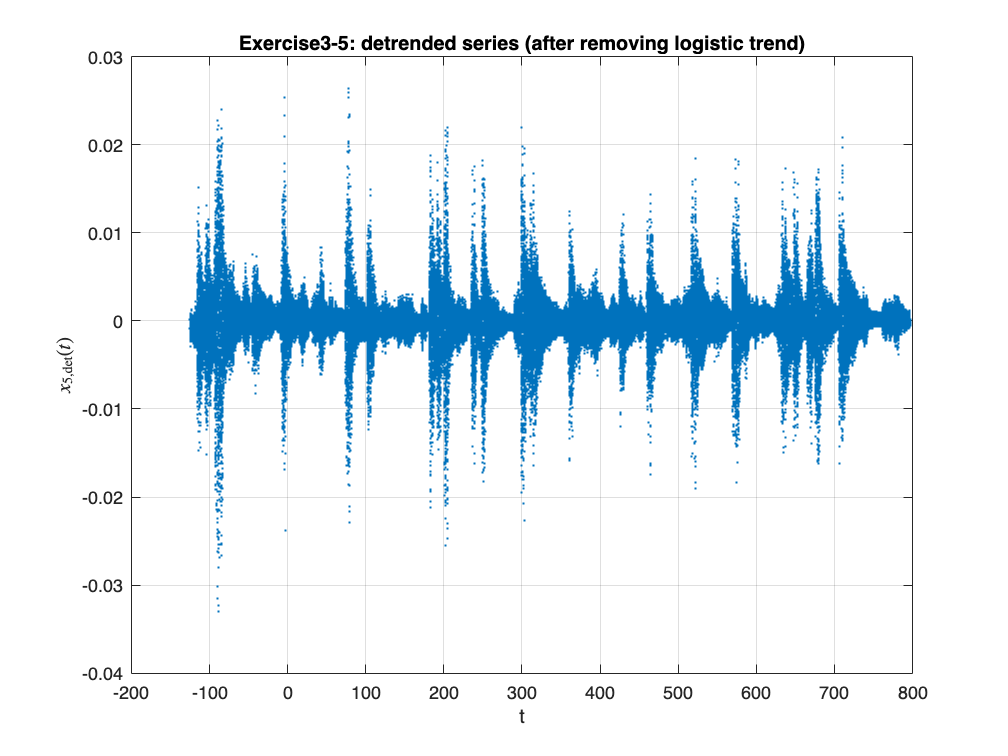



% Detrended series
figure;
plot(t5, x5_det, '.', 'MarkerSize', 3);
grid on;
xlabel('t');
ylabel('$x_{5,\mathrm{det}}(t)$', 'Interpreter', 'latex');
title('Exercise3-5: detrended series (after removing logistic trend)');


%% ================================================================
%  4) Series 6: Logistic trend without offset
%      x_6(t) = L / (1 + exp(-k (t - t0)))
%     Monotonic growth from near zero to a positive saturation level
% ================================================================

logistic_simple = @(p, t) p(1) ./ (1 + exp(-p(2) * (t - p(3))));
% p(1) = L   (upper asymptote)
% p(2) = k   (growth rate)
% p(3) = t0  (center of transition)

% Initial guesses
L0_6  = max(x6);
k0_6  = 0.01;
t0_6  = mean(t6);

p0_6 = [L0_6, k0_6, t0_6];

p6_hat = lsqcurvefit(logistic_simple, p0_6, t6, x6, [], [], opts);

L6  = p6_hat(1);
k6  = p6_hat(2);
t0_6 = p6_hat(3);

fprintf('--- Series 6: logistic model ---\n');

--- Series 6: logistic model ---


fprintf('x_6(t) = L / (1 + exp(-k (t - t0)))\n');

x_6(t) = L / (1 + exp(-k (t - t0)))


fprintf('L  = %.6g\n', L6);

L  = 1.57082


fprintf('k  = %.6g\n', k6);

k  = 0.00999922


fprintf('t0 = %.6g\n\n', t0_6);

t0 = -9.72332e-05



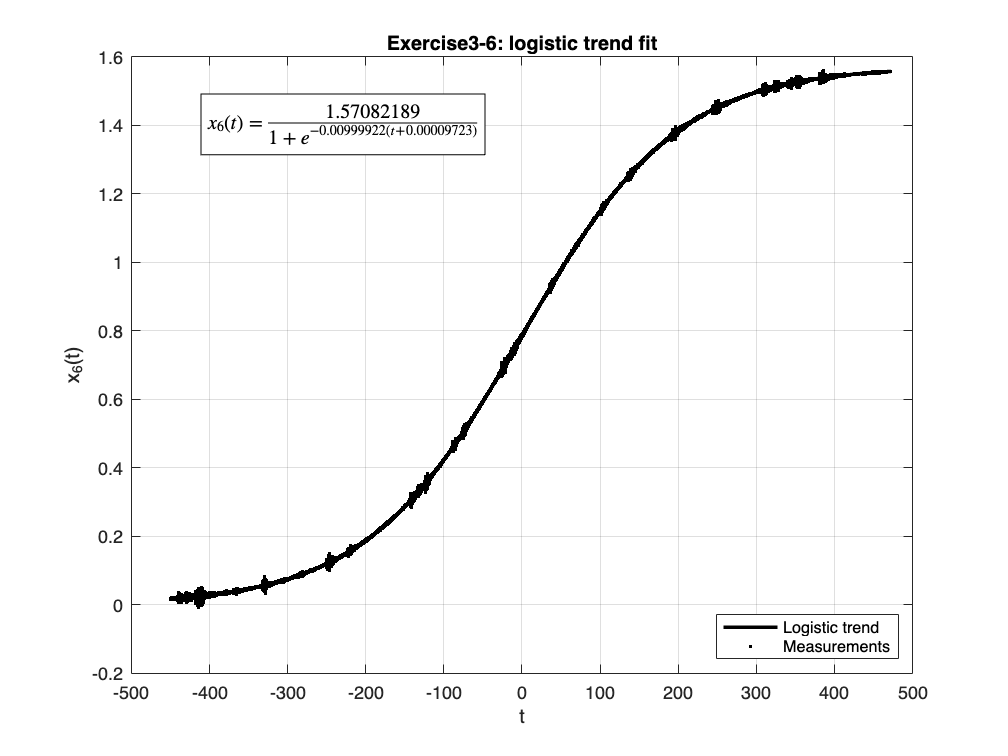


x6_trend = logistic_simple(p6_hat, t6);
x6_det   = x6 - x6_trend;

% Plot data + trend
figure;
plot(t6, x6_trend, 'LineWidth', 2, 'Color', [0 0 0]); hold on;   % Logistic trend line
plot(t6, x6, '.', 'MarkerSize', 5, 'Color', 'black');            % Measured data

grid on;
xlabel('t'); ylabel('x_6(t)');
title('Exercise3-6: logistic trend fit');
legend('Logistic trend','Measurements','Location','southeast');

% -----------------------------------------------------------
% Insert logistic equation inside the figure
% -----------------------------------------------------------

% Decide sign for (t ± t0)
if t0_6 >= 0
    sign_char = '-';
    t0_abs    = t0_6;
else
    sign_char = '+';
    t0_abs    = abs(t0_6);
end

% Build the LaTeX string using the estimated parameters
eq_str_6 = sprintf( ...
    '$x_6(t) = \\frac{%.8f}{1 + e^{-%.8f (t %c %.8f)}}$', ...
     L6, k6, sign_char, t0_abs);

% Choose position inside figure (adjust if needed)
xpos = min(t6) + 0.05 * (max(t6) - min(t6));
ypos = max(x6) - 0.10 * (max(x6) - min(x6));

% Draw the equation inside the plot
text(xpos, ypos, eq_str_6, 'Interpreter', 'latex', ...
     'FontSize', 11, 'BackgroundColor', 'white', 'EdgeColor', 'black');

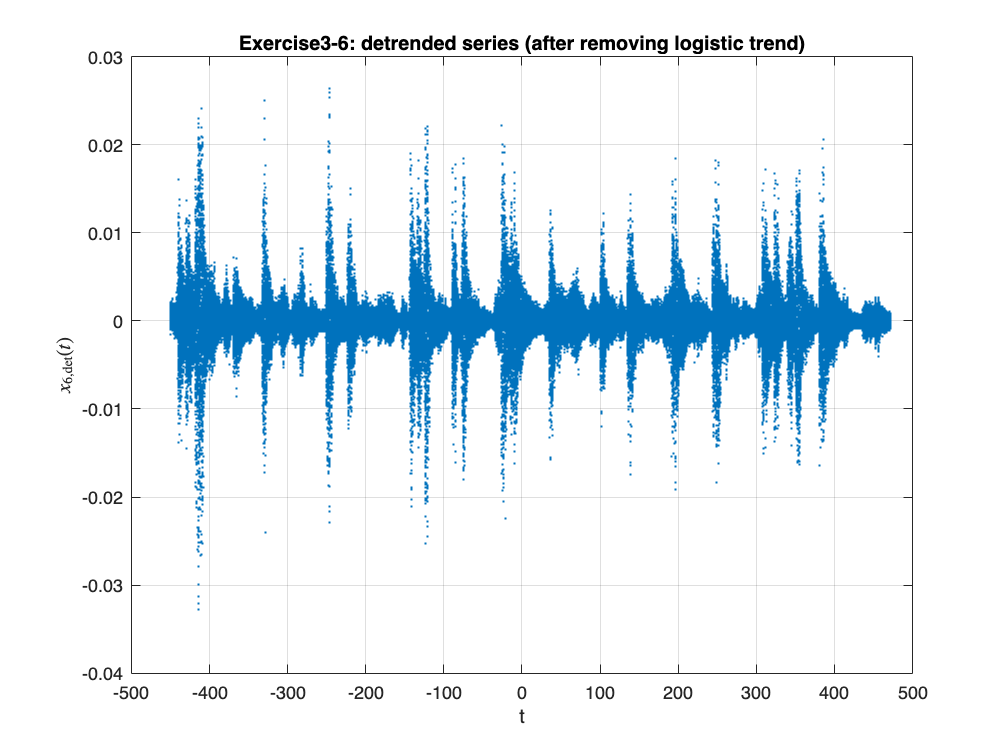



% Detrended series
figure;
plot(t6, x6_det, '.', 'MarkerSize', 3);
grid on;
xlabel('t');
ylabel('$x_{6,\mathrm{det}}(t)$', 'Interpreter', 'latex');
title('Exercise3-6: detrended series (after removing logistic trend)');

### Task 4. Differences in detrended series

%% ================================================================
%  Task 4: Compare detrended series from Exercise3-5 and Exercise3-6
% ================================================================

% Check that both time axes match
if ~isequal(t5, t6)
    warning('Time vectors differ. Interpolating x6_det to t5.');
    x6_det_interp = interp1(t6, x6_det, t5, 'linear');
else
    x6_det_interp = x6_det;
end

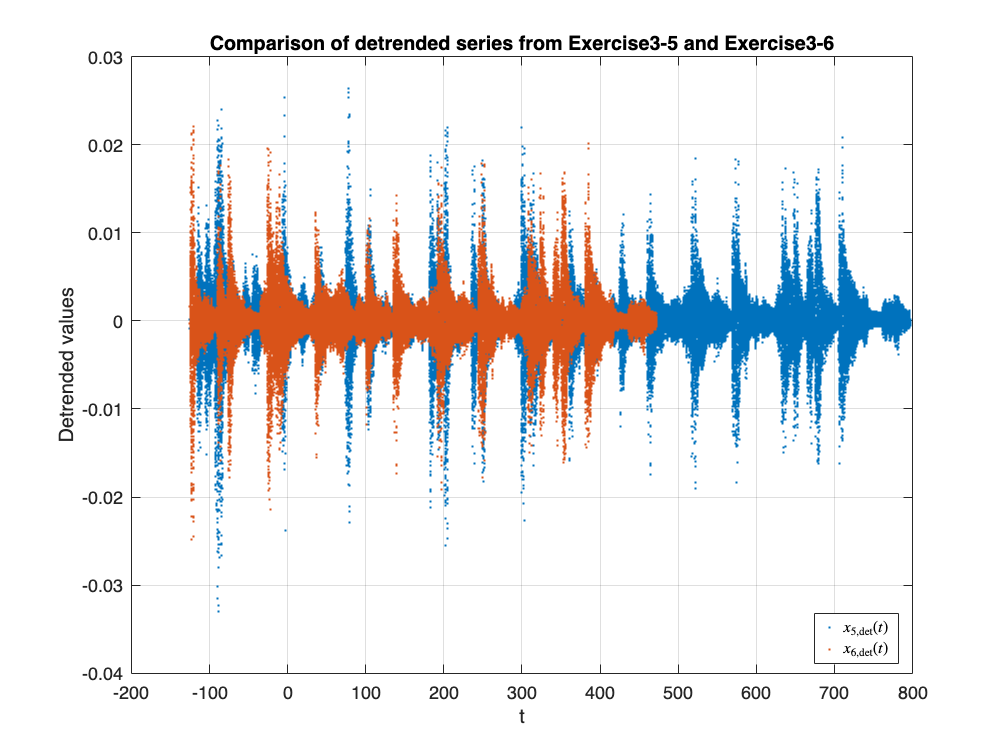


% Compute differences
diff_det = x5_det - x6_det_interp;

% Plot comparison of the two detrended series
figure;
plot(t5, x5_det, '.', 'MarkerSize', 4); hold on;
plot(t5, x6_det_interp, '.', 'MarkerSize', 4);
grid on;
xlabel('t');
ylabel('Detrended values');
title('Comparison of detrended series from Exercise3-5 and Exercise3-6');
legend('$x_{5,\mathrm{det}}(t)$', '$x_{6,\mathrm{det}}(t)$', ...
       'Interpreter', 'latex', 'Location', 'best');

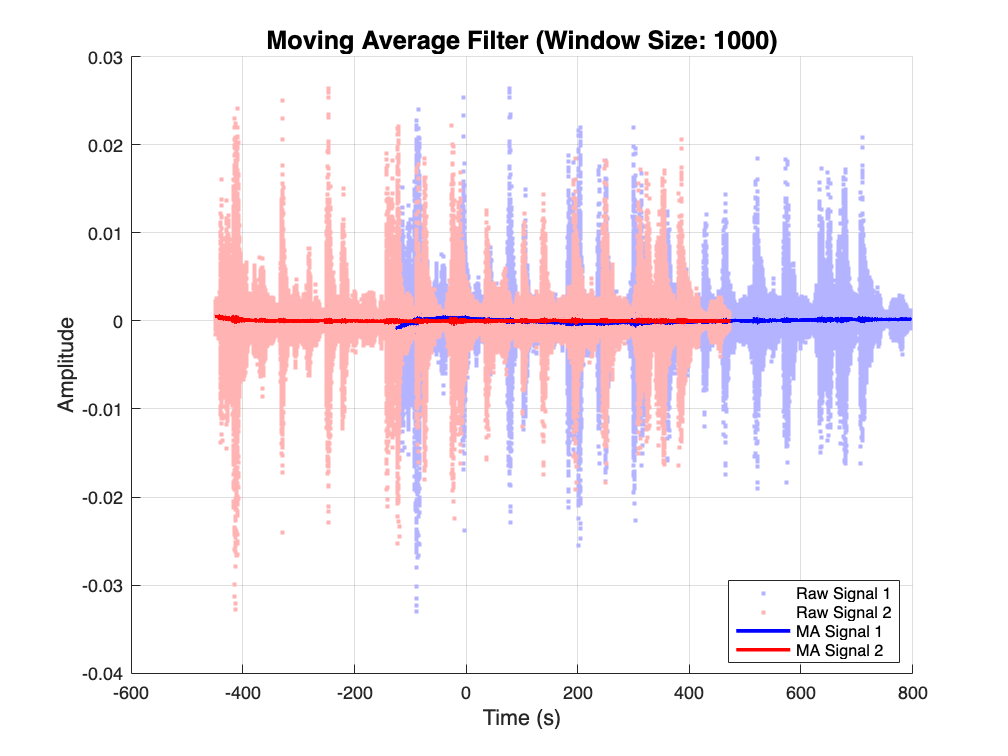

%% TASK


window_size = 1000; % The number of points to average over

% 'movmean' is the standard built-in function for moving averages
ma_signal_1 = movmean(x5_det, window_size);
ma_signal_2 = movmean(x6_det, window_size);

%% 3. Plotting
figure('Name', 'Moving Average Comparison', 'Color', 'w');
hold on; grid on;

% Optional: Plot raw data faintly for context
plot(t5, x5_det, '.', 'Color', [0.7 0.7 1], 'DisplayName', 'Raw Signal 1');
plot(t6, x6_det, '.', 'Color', [1 0.7 0.7], 'DisplayName', 'Raw Signal 2');

% Plot the Moving Averages (Thicker lines)
plot(t5, ma_signal_1, 'b-', 'LineWidth', 2, 'DisplayName', 'MA Signal 1');
plot(t6, ma_signal_2, 'r-', 'LineWidth', 2, 'DisplayName', 'MA Signal 2');

% Formatting
title(['Moving Average Filter (Window Size: ' num2str(window_size) ')'], 'FontSize', 14);
xlabel('Time (s)', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
legend('Location', 'best');

hold off;




% 
% % Plot their difference
% figure;
% plot(t5, diff_det, '.', 'MarkerSize', 4);
% grid on;
% xlabel('t');
% ylabel('$x_{5,\mathrm{det}}(t) - x_{6,\mathrm{det}}(t)$', ...
%     'Interpreter', 'latex');
% title('Differences between detrended time series (should be zero)');
